This script simulates a QPSK(Quadrature phase shift keying)digital communication transmision chain.It generates random binary data,maps them to complex sympols, introduces Additive White Gaussian Noise(AWGN) to simulate a noisy wireless environment, and plots the resulting constellation diagram.

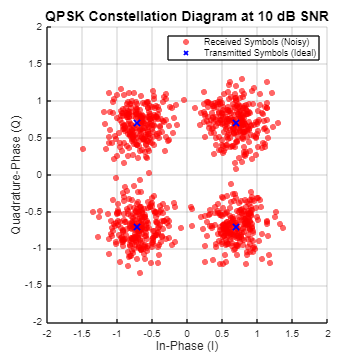

% QPSK Modulation and AWGN Channel Simulation
clear; clc; close all;

% 1. Parameters
numSymbols = 1000;
snrDB = 10; % Signal-to-Noise Ratio in dB

% 2. Generate random binary data (0s and 1s)
dataBits = randi([0, 1], numSymbols * 2, 1);

% 3. QPSK Modulation (Gray coding mapping)
% Map bit pairs to complex QPSK symbols: 00 -> -1-j, 01 -> -1+j, 11 -> 1+j, 10 -> 1-j
I = 2 * dataBits(1:2:end) - 1;
Q = 2 * dataBits(2:2:end) - 1;
txSymbols = (I + 1j * Q) / sqrt(2); % Power normalization

% 4. Simulate Wireless Channel (Add AWGN)
snrLinear = 10^(snrDB / 10);
noiseVariance = 1 / snrLinear;
% Generate complex Gaussian noise
noise = sqrt(noiseVariance / 2) * (randn(numSymbols, 1) + 1j * randn(numSymbols, 1));

% Received symbols
rxSymbols = txSymbols + noise;

% 5. Plotting the Results
figure('Color', 'white', 'Position', [100, 100, 600, 600]);
scatter(real(rxSymbols), imag(rxSymbols), 40, 'r', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(real(txSymbols), imag(txSymbols), 80, 'bx', 'LineWidth', 2);

title(sprintf('QPSK Constellation Diagram at %d dB SNR', snrDB), 'FontSize', 14);
xlabel('In-Phase (I)', 'FontSize', 12);
ylabel('Quadrature-Phase (Q)', 'FontSize', 12);
grid on;
legend('Received Symbols (Noisy)', 'Transmitted Symbols (Ideal)', 'Location', 'northeast');
xlim([-2, 2]);
ylim([-2, 2]);